## Phase Modulation and Demodulation

% Clear workspace and close figures
clc;
close all;
clear all;

% Load the audio file
audioFile = 'videoplayback.wav';
[x, fs] = audioread(audioFile);

t = (0:length(x) - 1) / fs; % Time vector

% Split audio into left and right channels
l = x(:, 1); % Left audio
r = x(:, 2); % Right audio

demod = zeros(size(x)); % Initialize an array to store the demodulated output

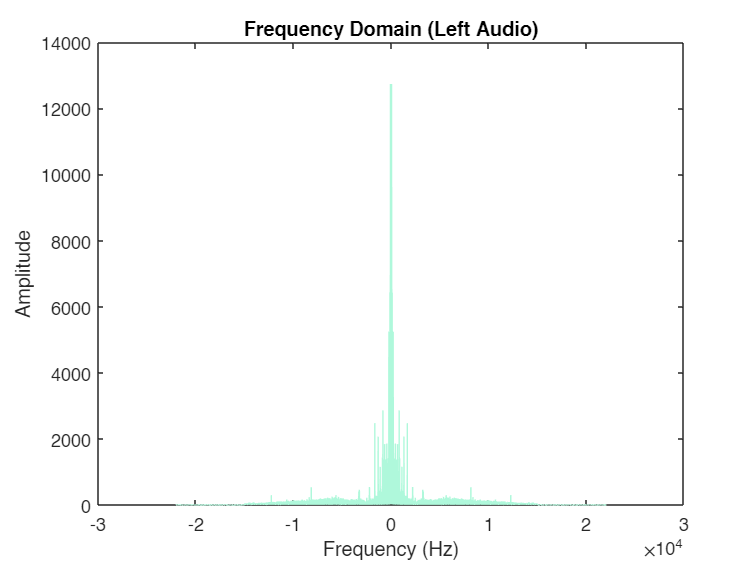

% Plot the original signal in the frequency domain (Left Audio)
L = fft(l);
f = (-length(L)/2:length(L)/2 - 1) * fs / length(L);

figure;
plot(f, abs(fftshift(L)), 'Color', '#aff8db');
title('Frequency Domain (Left Audio)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

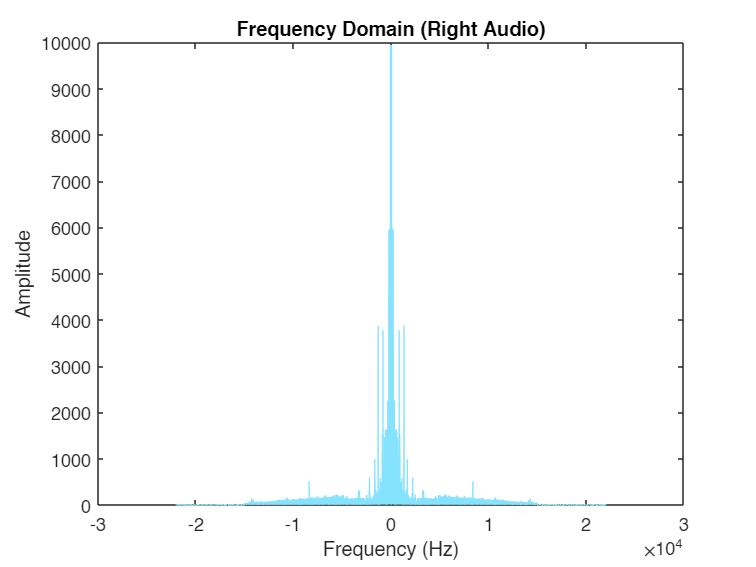

% Plot the original signal in the frequency domain (Right Audio)
R = fft(r);
f = (-length(R)/2:length(R)/2 - 1) * fs / length(R);

figure;
plot(f, abs(fftshift(R)), 'Color', '#85e3ff');
title('Frequency Domain (Right Audio)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

fc = 1e6; % Carrier frequency

% Carrier Wave
wc = 2 * pi * fc * t;
wc = reshape(wc, size(l));

% Defining modulation indices
mu = [0.05, 0.1, 0.5, 0.75, 1, 2];

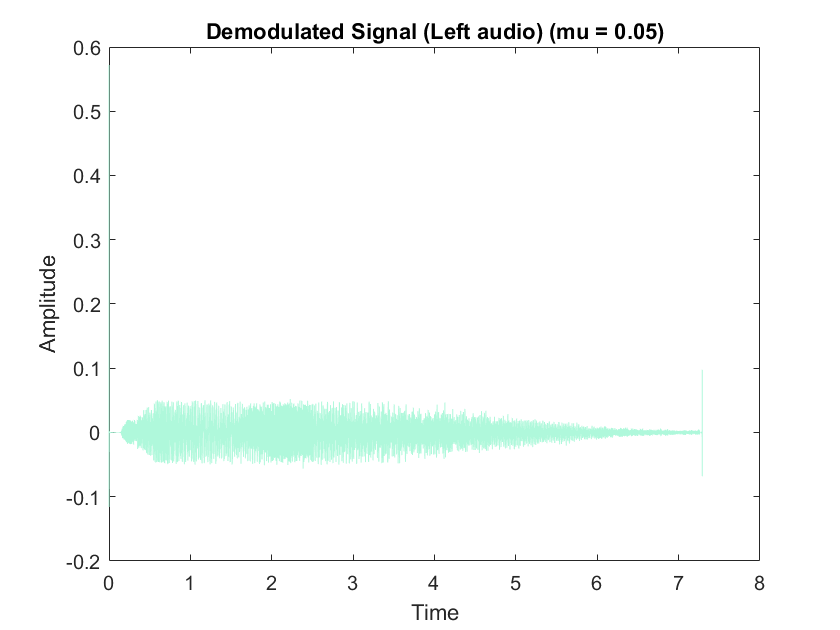

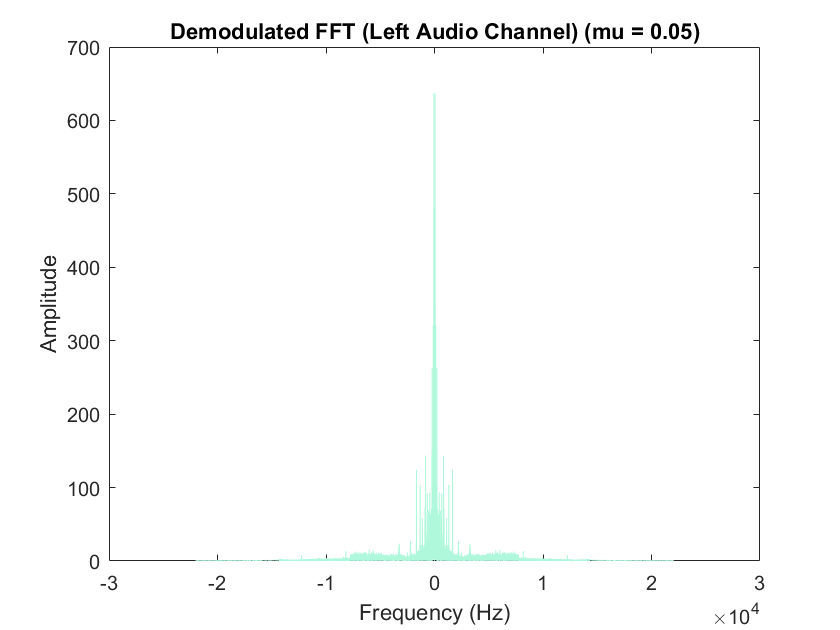

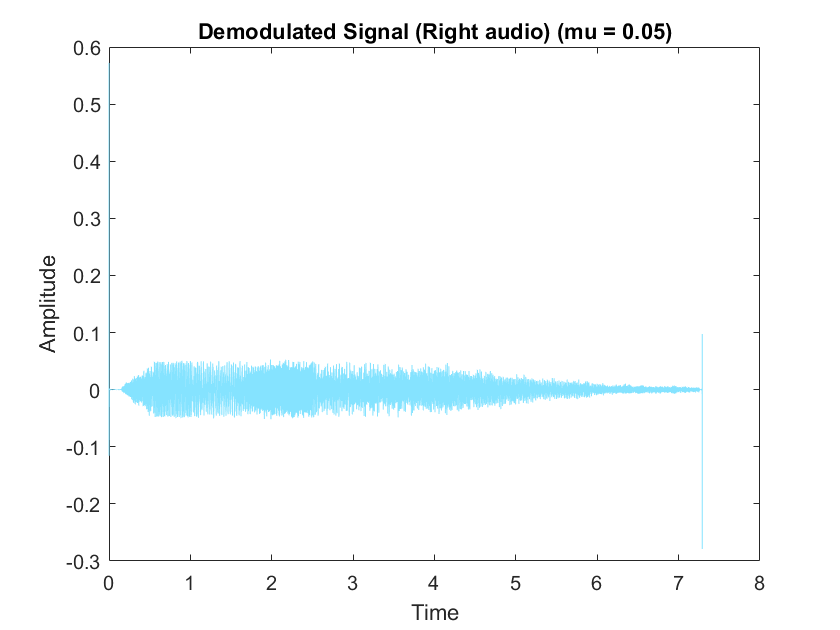

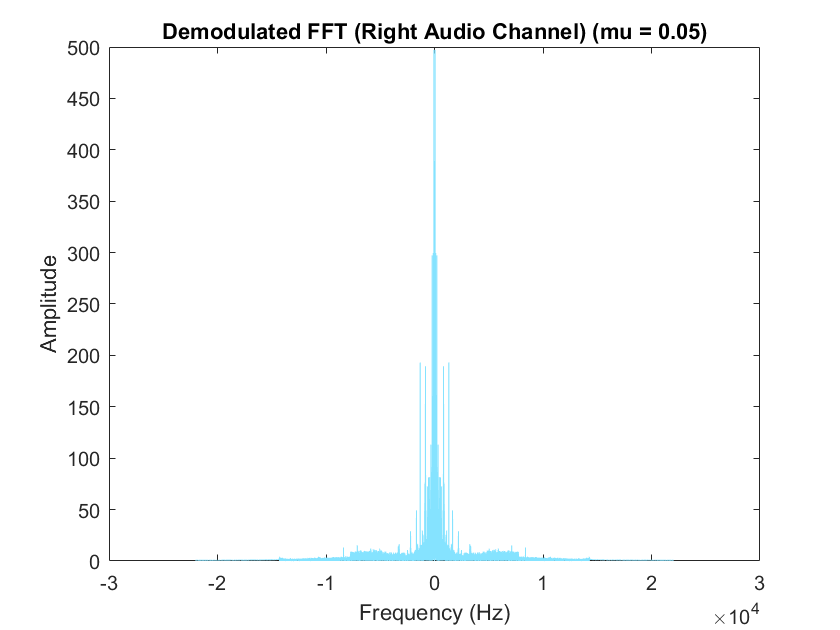

Playing demodulated audio (mu = 0.05)


Audio playback completed.


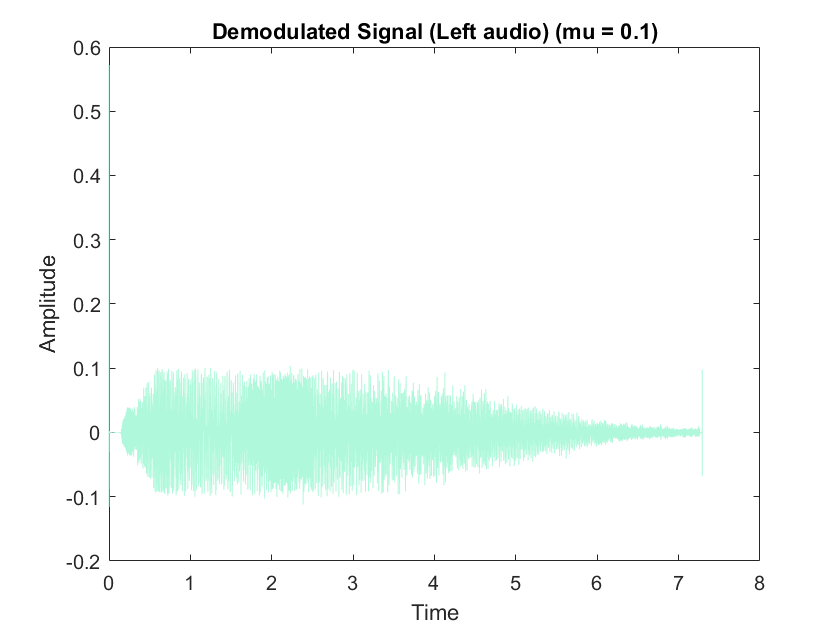

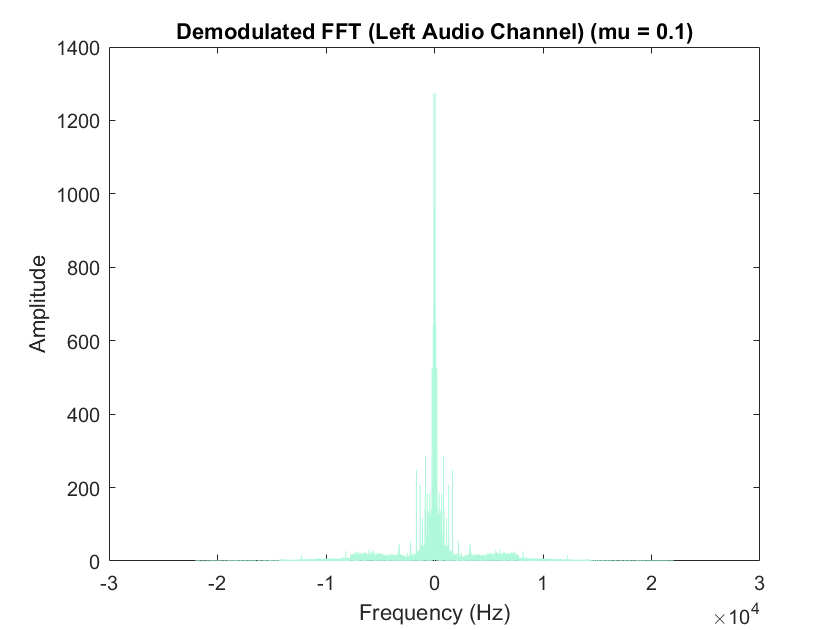

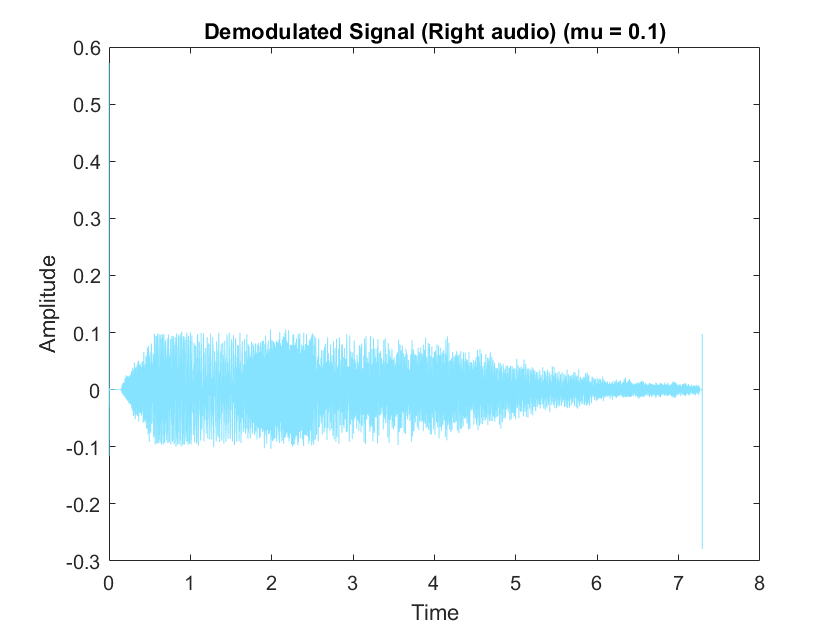

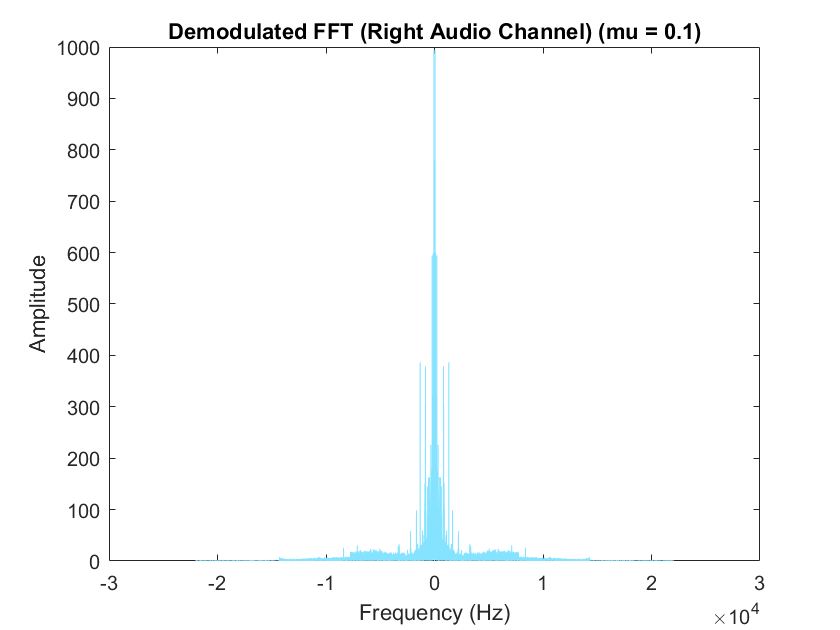

Playing demodulated audio (mu = 0.1)


Audio playback completed.


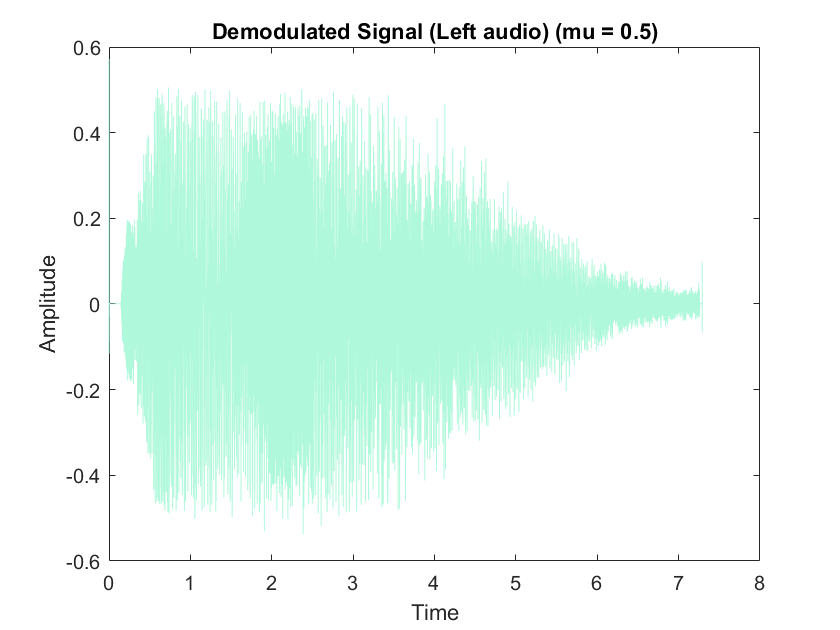

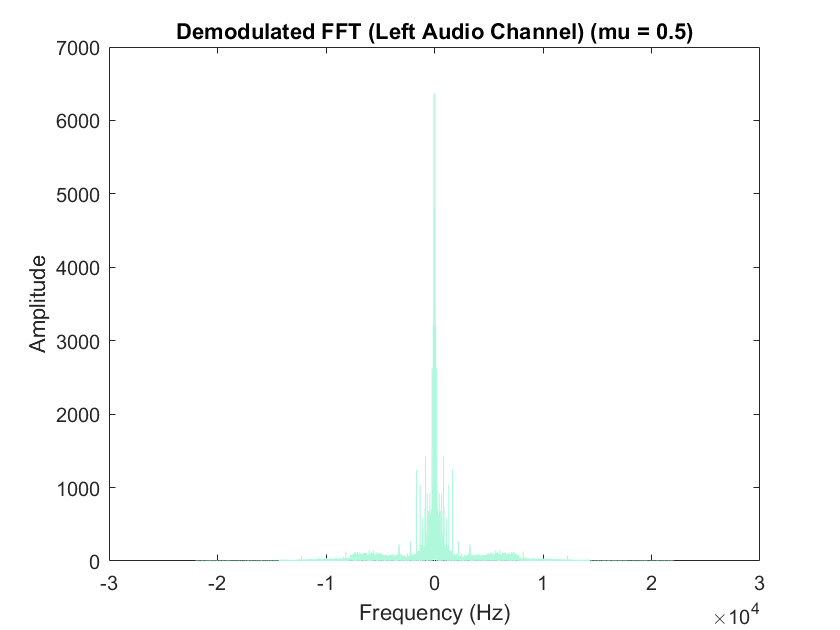

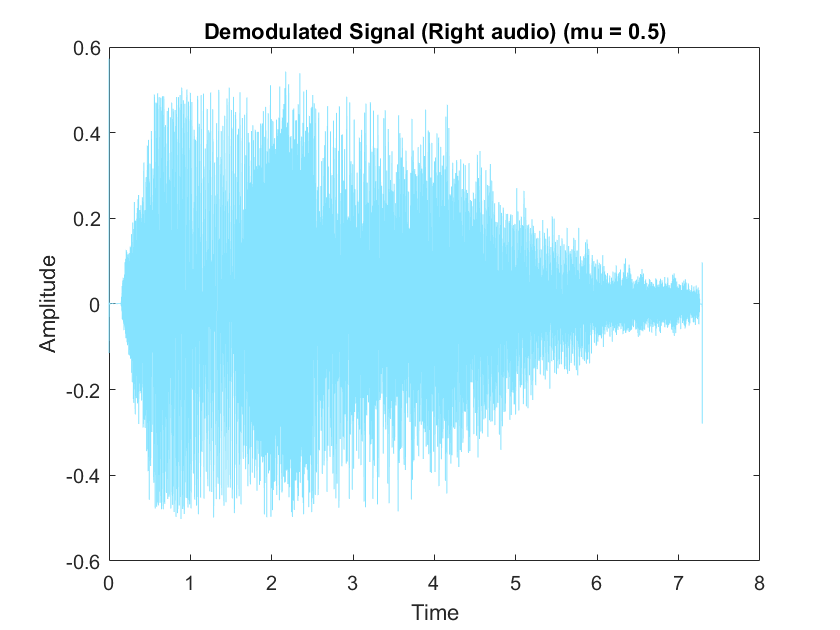

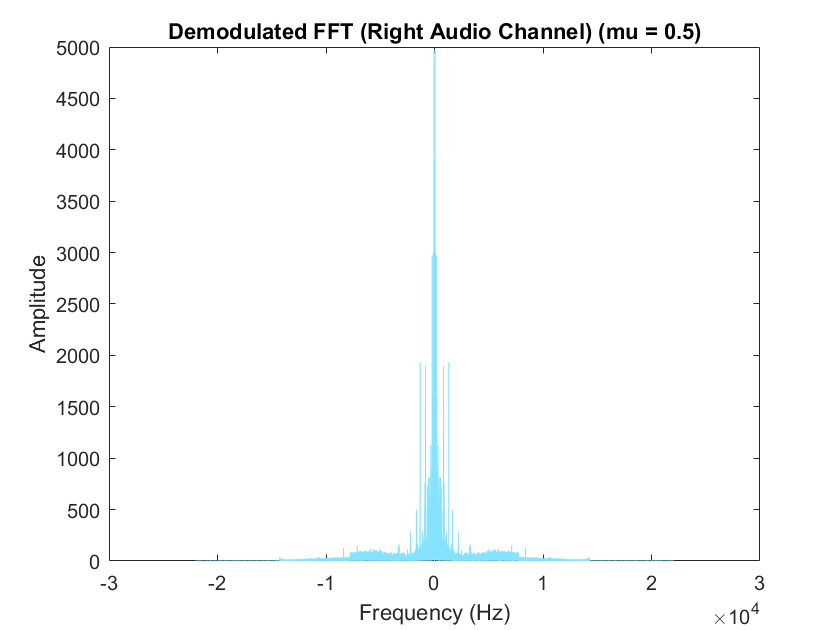

Playing demodulated audio (mu = 0.5)


Audio playback completed.


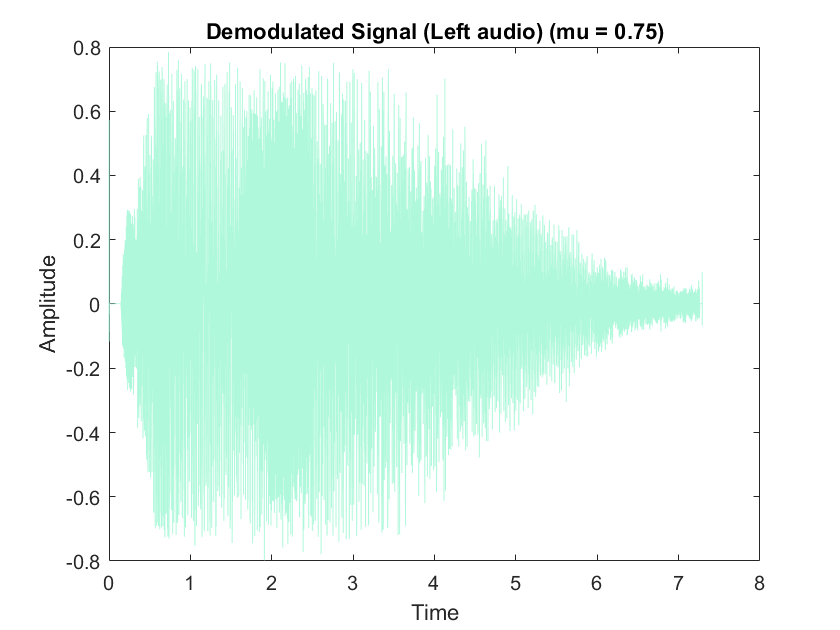

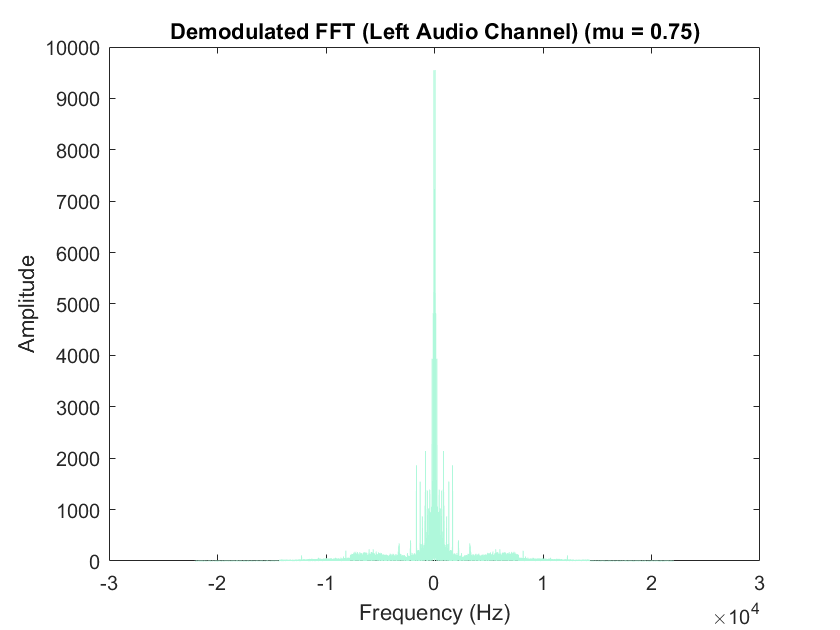

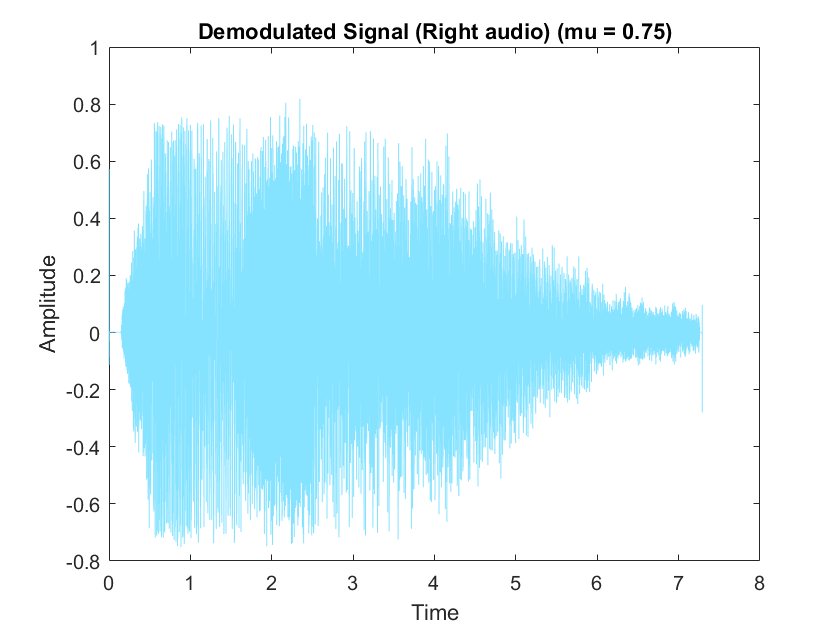

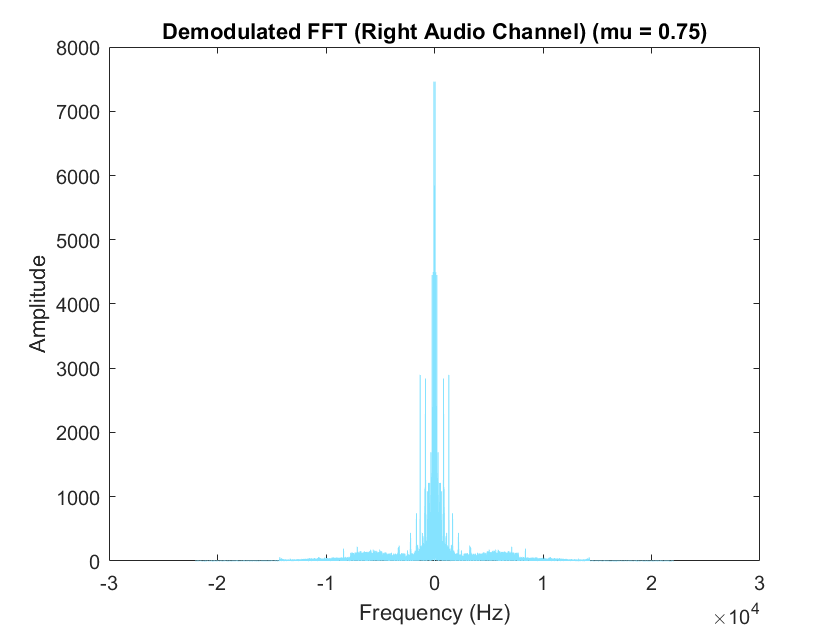

Playing demodulated audio (mu = 0.75)


Audio playback completed.


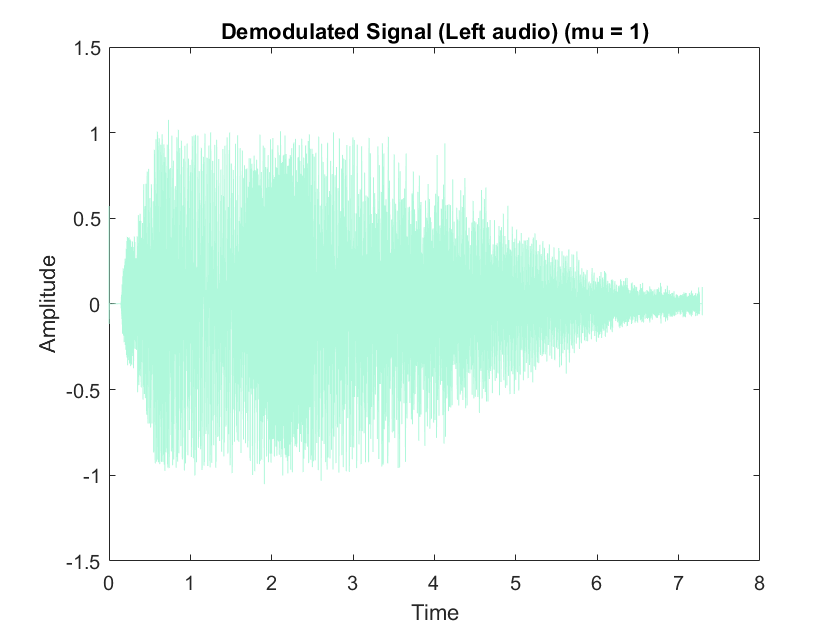

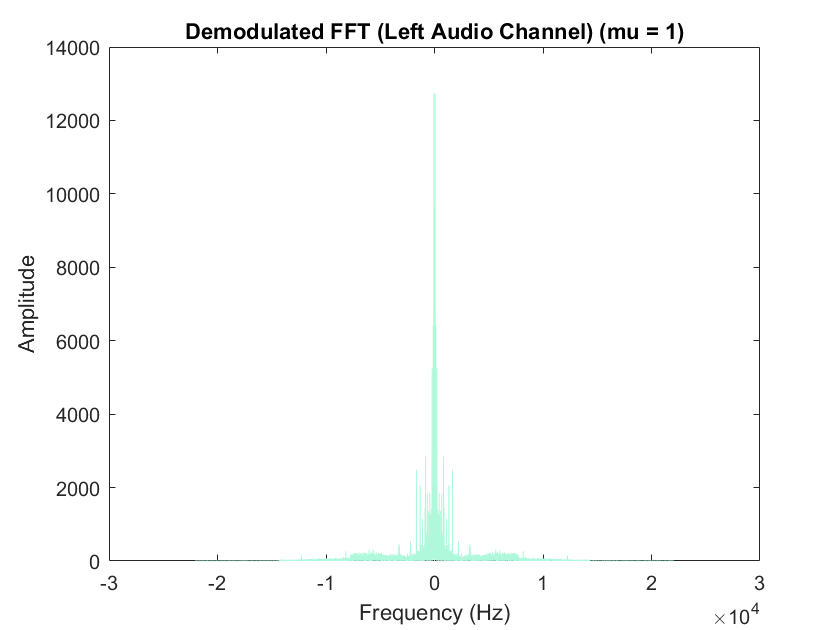

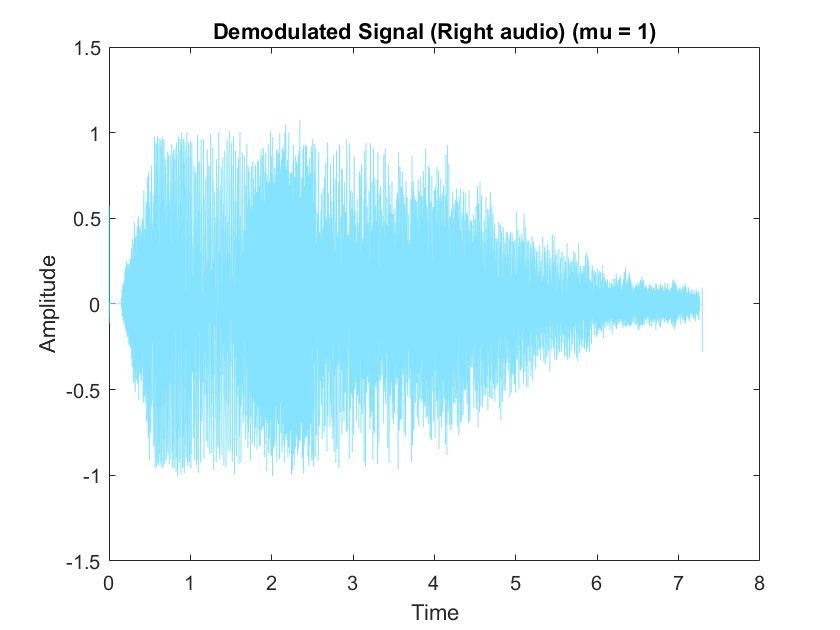

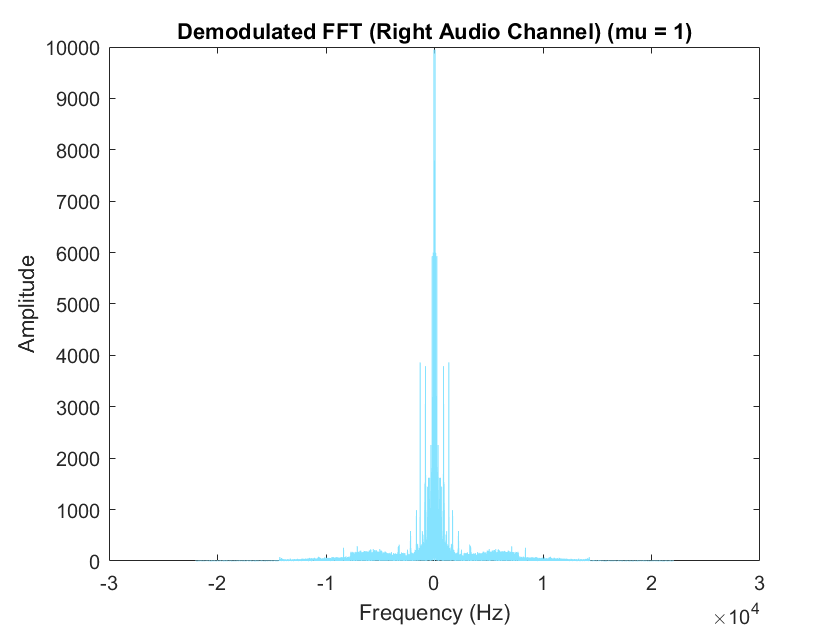

Playing demodulated audio (mu = 1)


Audio playback completed.


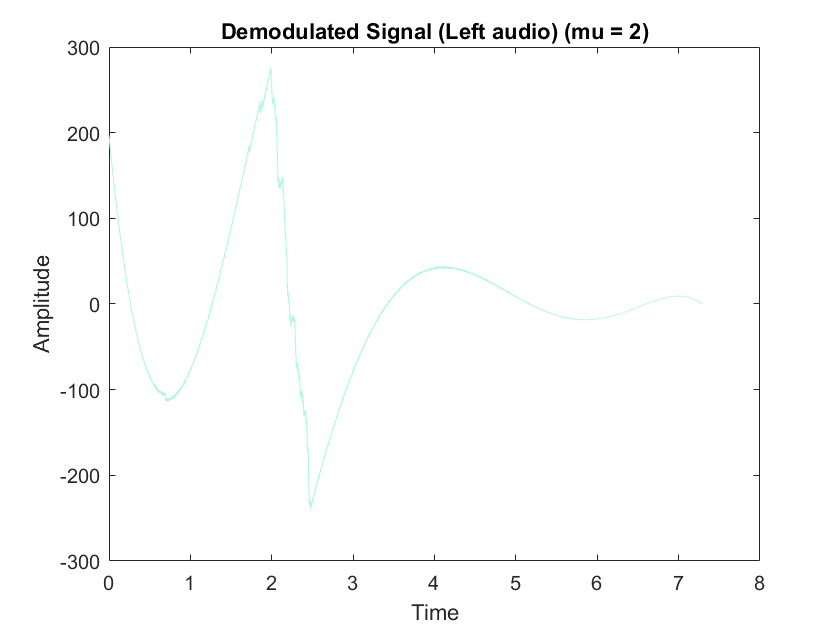

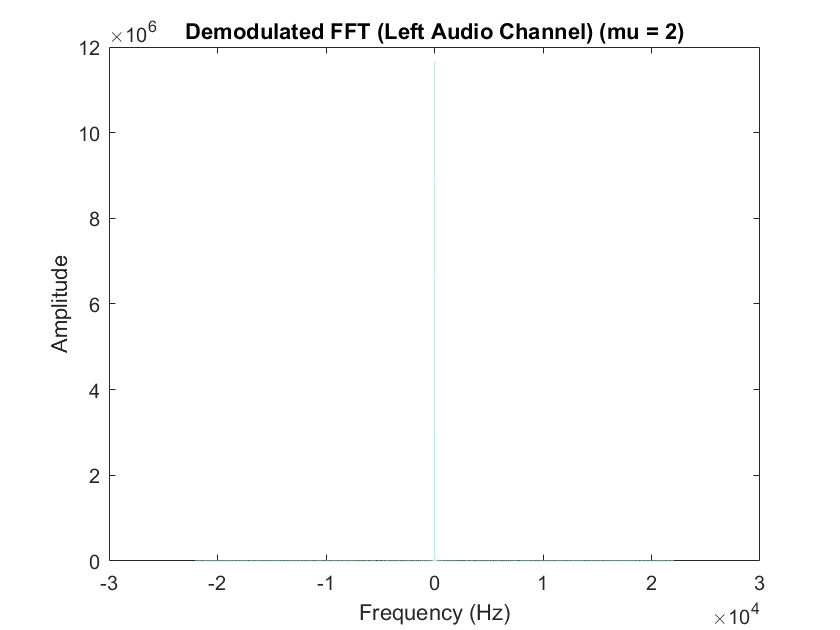

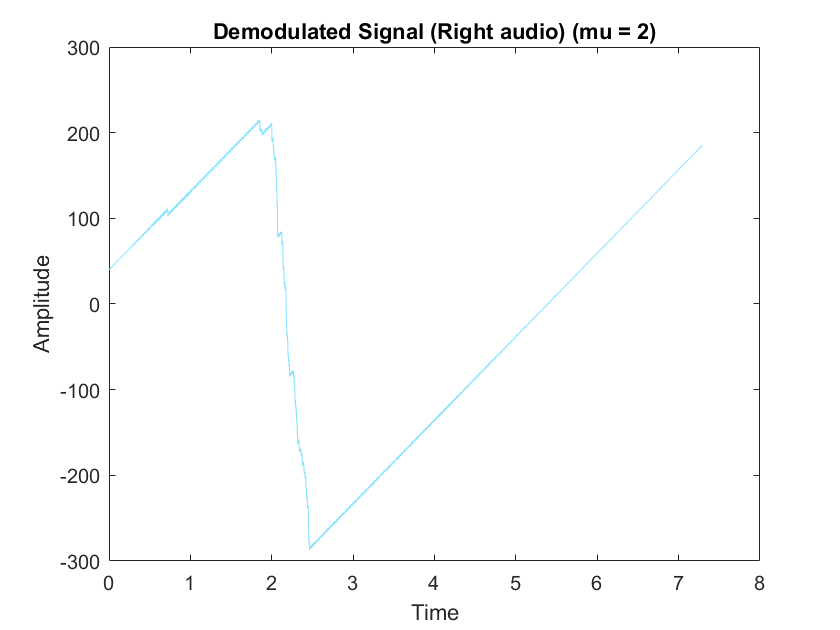

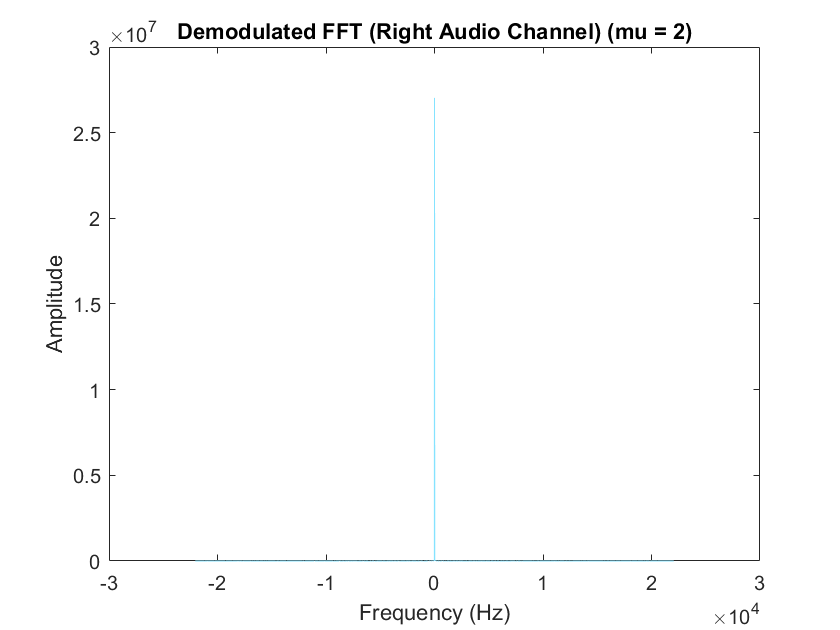

Playing demodulated audio (mu = 2)


Audio playback completed.


for i = 1:length(mu)
    
    % Modulating left audio signal    
    left_channel = cos(wc + mu(i) * l);
    
    % Modulating right audio signal
    right_channel = cos(wc + mu(i) * r); 
    
    % Demodulation
    left_hilb = hilbert(left_channel);
    right_hilb = hilbert(right_channel);
    
    inst_phase_l = unwrap(angle(left_hilb)); % Instantaneous phase
    inst_phase_r = unwrap(angle(right_hilb));
    
    % Processing Left Audio Channel

    % Assume that the carrier is not available and estimate it from the phase
    p = polyfit(t, inst_phase_l, 5); % Fit the instantaneous phase
    estimated = polyval(p, t); % Re-evaluate the offset term using the fitted values
    offset = reshape(estimated, size(inst_phase_l));
    
    demod(:, 1) = inst_phase_l - offset;
    demod(length(demod), 1) = 0; % Set the last sample to zero

    % Plot the demodulated signal in the time domain (Left Audio)
    figure;
    plot(t, demod(:, 1), 'Color', '#aff8db');
    title(['Demodulated Signal (Left audio) (mu = ', num2str(mu(i)), ')']);
    xlabel('Time');
    ylabel('Amplitude');

    Y_L = fftshift(fft(demod(:, 1)));
    f = (-length(Y_L)/2:length(Y_L)/2 - 1) * fs / length(Y_L);

    % Plot the demodulated signal in the frequency domain (Left Audio)
    figure;
    plot(f, abs(Y_L), 'Color', '#aff8db');
    title(['Demodulated FFT (Left Audio Channel) (mu = ', num2str(mu(i)), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');

    % Processing Right Audio Channel

    % Assume that the carrier is not available and estimate it from the phase
    p = polyfit(t, inst_phase_r, 1); % Fit the instantaneous phase
    estimated = polyval(p, t); % Re-evaluate the offset term using the fitted values
    offset = reshape(estimated, size(inst_phase_r));
    
    demod(:, 2) = inst_phase_r - offset;
    
    % Plot the demodulated signal in the time domain (Right Audio)
    figure;
    plot(t, demod(:, 2), 'Color', '#85e3ff');
    title(['Demodulated Signal (Right audio) (mu = ', num2str(mu(i)), ')']);
    xlabel('Time');
    ylabel('Amplitude');

    Y_R = fftshift(fft(demod(:, 2)));
    f = (-length(Y_R)/2:length(Y_R)/2 - 1) * fs / length(Y_R);

    % Plot the demodulated signal in the frequency domain (Right Audio)
    figure;
    plot(f, abs(Y_R), 'Color', '#85e3ff');
    title(['Demodulated FFT (Right Audio Channel) (mu = ', num2str(mu(i)), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    
    % Play the demodulated audio (uncomment the following lines to enable audio playback)
    disp(['Playing demodulated audio (mu = ', num2str(mu(i)), ')']); 
    soundsc(demod, fs); % Use sound to play the final audio
    pause(length(x) / fs); % Pause to allow time for audio playback
    disp('Audio playback completed.');
end